% This is the completed OFDM simulation code
% Create a resource block too

% with AWGN,  no Doppler 
% With pilot symbols
% channel gain - tapped daley
% channel estimation: Zero-forcing plus linear interpoloation
% would expect a better performance than no CE
% Need to fix the OFDM first
% Both BER metrics are the same


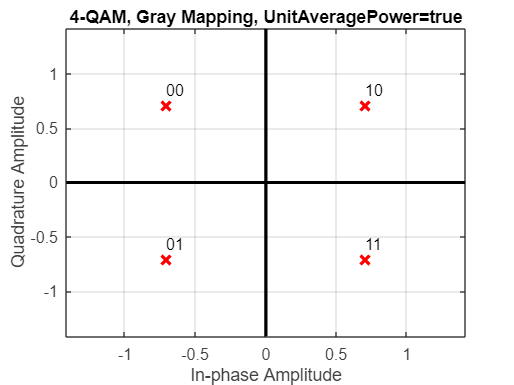

% Parameter definition
total_subchannels = 12;                        % Total number of subchannels
all_indices = 1:1:total_subchannels;           % Indices of all subcarriers (0 to K-1)
cp_length = total_subchannels / 4;             % Cyclic prefix length
modulation_order = 4;                          % Modulation order
% channel_length = 1;                            % Channel length
max_iterations = 10;                         % Number of iterations in each evaluation
SNR_vector = 0:1:10;                           % Signal-to-noise ratio vector in dB
bits_len = total_subchannels * log2(modulation_order);
total_bit_error_count_threshold = 100;

% Determine the number of pilot symbols and spacing
num_pilots= min(6, total_subchannels); % Maximum 4 pilot symbols

% Generate pilot bits and symbols
pilot_bits_len = num_pilots * log2(modulation_order);
pilot_bits = randi([0 1], pilot_bits_len, 1);
pilot_symbols = qammod(pilot_bits, 4, 'InputType', 'bit', 'UnitAveragePower', true, PlotConstellation=true);


% Generate indices of pilot symbols
pilot_indices = zeros(num_pilots, 1);

% Ensure the last subcarrier is a pilot
pilot_indices(1) = 1;
pilot_indices(num_pilots) = total_subchannels;

% Calculate pilot spacing
pilot_spacing = (total_subchannels - 1) / (num_pilots - 1);

% Generate indices of equally spaced pilot symbols
for i = 2:num_pilots-1
    pilot_indices(i) = round((i - 1) * pilot_spacing);
end

data_bits_len = bits_len - pilot_bits_len;
data_indices = setxor(1:total_subchannels, pilot_indices); % Indices of data subchannels

% number of dmrs columns
pilot_col_num = 2;
pilot_symbols_num = pilot_col_num * num_pilots % total number of pilot symbols

pilot_symbols_num = 12

% generate resource block data length
block_data_bits_len = (12 * 14 - pilot_symbols_num) * log2(modulation_order)

block_data_bits_len = 312


resource_block = generate_resource_block(block_data_bits_len, pilot_symbols, pilot_indices, modulation_order)

resource_block =    0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i
  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i
   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i
  -0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 +


% Initialize array to store BER values
total_bit_error_count_array = zeros(length(SNR_vector), 1);
total_bit_error_count_array_no_ce = zeros(length(SNR_vector), 1);
total_bit_error_count_array_my_fn = zeros(length(SNR_vector), 1);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Known channel response
% Define the impulse response of the wireless channel
want_channel_freq = ones(total_subchannels, 1) * 10

want_channel_freq =     10
    10
    10
    10
    10
    10
    10
    10
    10
    10


channel_response = ifft(want_channel_freq,1)

channel_response = 10

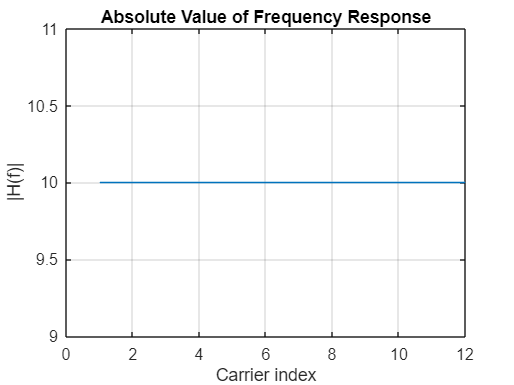


% channel_response = [1, 0, 0.3+0.3j, 0.5];  % Impulse response of the wireless channel
%



% Calculate the FFT
H_exact = fft(channel_response, total_subchannels);

% Plot the absolute value of H_exact
figure;
plot(all_indices, abs(H_exact));
xlabel('Carrier index');
ylabel('|H(f)|');
title('Absolute Value of Frequency Response');
grid on;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
constDiagram = comm.ConstellationDiagram;

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

total_bit_error_count_my_fn = 0

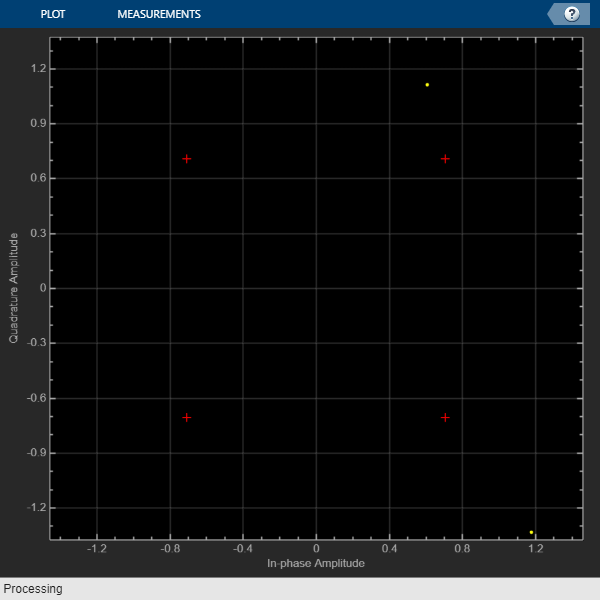


for snr_index = 1:length(SNR_vector)
    SNR_dB = SNR_vector(snr_index);
    total_bit_error_count = 0;
    total_bit_error_count_no_ce = 0; % Initialize count for each SNR
    total_bit_error_count_my_fn =  0

    for iteration = 1:max_iterations     
        % Generate data bits
        tx_data_bits = randi([0 1], (bits_len - num_pilots * log2(modulation_order)), 1);      

        % Modulate data bits
        tx_data_symbols = qammod(tx_data_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
        
        % Combine data symbols with pilot symbols
        tx_all_symbols = zeros(total_subchannels, 1);
        tx_all_symbols(pilot_indices) = pilot_symbols;
        tx_all_symbols(setdiff(1:total_subchannels, pilot_indices)) = tx_data_symbols;        

        % Perform IFFT
        tx_data_ifft = ifft(tx_all_symbols, total_subchannels);
        
        % Add CP
        tx_data_ifft_with_cp = [tx_data_ifft(total_subchannels - cp_length + 1 : total_subchannels); tx_data_ifft];

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        % Transmission through the channel
        rx_data_ifft_with_cp = conv(tx_data_ifft_with_cp, channel_response);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        rx_data_ifft_with_cp_and_noise = awgn(rx_data_ifft_with_cp, SNR_dB, 'measured');
%         rx_data_ifft_with_cp_and_noise = rx_data_ifft_with_cp;
        constDiagram(rx_data_ifft_with_cp_and_noise);

        % Remove CP (time)
        % TODO: Correct dimensions?
        rx_data_ifft_np_cp = rx_data_ifft_with_cp_and_noise(cp_length + 1 : cp_length + total_subchannels);
        
        % Perform FFT (freq)
        rx_all_symbols_no_ce= fft(rx_data_ifft_np_cp, total_subchannels);
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        % Calculate BER without CE
        % Extract data_symbols
        rx_data_symbols_no_ce = rx_all_symbols_no_ce(data_indices);

        % Demodulation only data symbols - using nearest euclidean distance
        rx_data_bits_no_ce = qamdemod(rx_data_symbols_no_ce, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count_no_ce = sum(rx_data_bits_no_ce ~= tx_data_bits);
        total_bit_error_count_no_ce = total_bit_error_count_no_ce + bit_error_count_no_ce ;

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

        % Perform Channel estimation
        Hest = channelEstimate(rx_all_symbols_no_ce, pilot_indices, pilot_symbols, all_indices, H_exact);

        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
%         min_distance_qpsk_demodulation(rx_all_symbols_no_ce)

        % Perform equalisation
        rx_all_symbols = rx_all_symbols_no_ce ./ Hest;

        
        % Extract data_symbols
        rx_data_symbols = rx_all_symbols(data_indices);

        % Demodulation only data symbols - using nearest euclidean distance
        rx_data_bits = qamdemod(rx_data_symbols, modulation_order, 'OutputType', 'bit');

        % Count error bits
        bit_error_count = sum(rx_data_bits ~= tx_data_bits);
        total_bit_error_count = total_bit_error_count + bit_error_count;

        % my function
        rx_fn_ip = rx_all_symbols_no_ce(data_indices).';
        rx_fn_hest = Hest(data_indices).';
        recovered_bits = min_distance_qpsk_demodulation(rx_fn_ip, rx_fn_hest);
       
        bit_error_count_my_fn = sum(recovered_bits ~= tx_data_bits);
        total_bit_error_count_my_fn = total_bit_error_count_my_fn + bit_error_count;
        
        % Breaking condition
        if total_bit_error_count > total_bit_error_count_threshold
            break
        end
    end

    

    % Calculate BER without Ce
    ber_no_ce = total_bit_error_count_no_ce / (iteration * data_bits_len);
    total_bit_error_count_array_no_ce(snr_index) = ber_no_ce;

    % Calculate BER
    ber = total_bit_error_count / (iteration * data_bits_len);
    total_bit_error_count_array(snr_index) = ber;

    % Calculate BER with my method
    ber_my_fn = total_bit_error_count_my_fn / (iteration * data_bits_len);
    total_bit_error_count_array_my_fn(snr_index) = ber_my_fn;
end

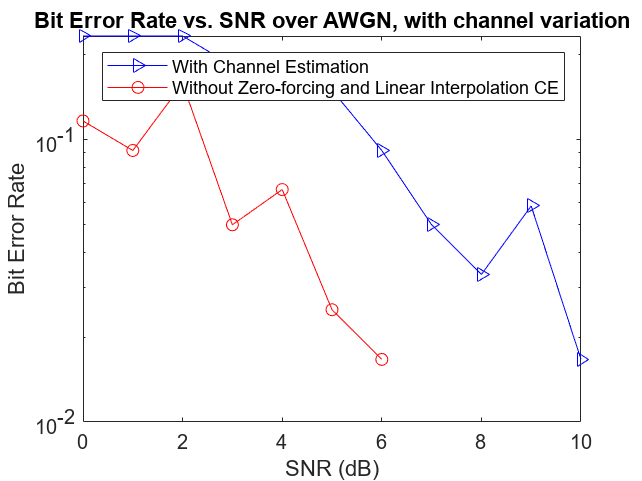



% Plotting
figure;
semilogy(SNR_vector, total_bit_error_count_array, 'b->');
hold on;
semilogy(SNR_vector, total_bit_error_count_array_no_ce, 'r-o');

xlabel('SNR (dB)');
ylabel('Bit Error Rate');
title('Bit Error Rate vs. SNR over AWGN, with channel variation');

legend('With Channel Estimation', 'Without Zero-forcing and Linear Interpolation CE');


total_bit_error_count_array_no_ce

total_bit_error_count_array_no_ce =     0.1167
    0.0917
    0.1583
    0.0500
    0.0667
    0.0250
    0.0167
         0
         0
         0


total_bit_error_count_array

total_bit_error_count_array =     0.2333
    0.2333
    0.2333
    0.1833
    0.1500
    0.1500
    0.0917
    0.0500
    0.0333
    0.0583


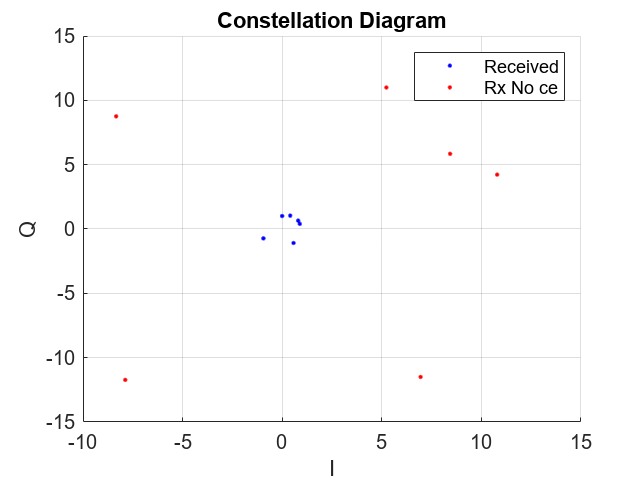

%%

% Plot constellation diagram after the loop
figure;
scatter(real(rx_data_symbols), imag(rx_data_symbols), 'b.');
hold on;
scatter(real(rx_data_symbols_no_ce), imag(rx_data_symbols_no_ce), 'r.');
xlabel('I');
ylabel('Q');
title('Constellation Diagram');
legend('Received', 'Rx No ce');
grid on;

total_bit_error_count_array_my_fn

total_bit_error_count_array_my_fn =     0.2333
    0.2333
    0.2333
    0.1833
    0.1500
    0.1500
    0.0917
    0.0500
    0.0333
    0.0583


total_bit_error_count_array

total_bit_error_count_array =     0.2333
    0.2333
    0.2333
    0.1833
    0.1500
    0.1500
    0.0917
    0.0500
    0.0333
    0.0583


function Hest = channelEstimate(rx_all_symbols_no_ce, pilot_indices, pilot_symbols, all_indices, H_exact)
    
    % Extract the pilot values from the RX signal
    rx_pilots_symbols = rx_all_symbols_no_ce(pilot_indices);
    
    % Divide by the transmitted pilot values to obtain channel estimate at pilots
    Hest_at_pilots = rx_pilots_symbols ./ pilot_symbols;
    
    % Perform interpolation between the pilot carriers to get an estimate
    % of the channel in the data carriers. Here, we interpolate absolute value and phase 
    % separately
    Hest_abs = interp1(pilot_indices, abs(Hest_at_pilots), all_indices, 'spline', 'extrap');
    Hest_phase = interp1(pilot_indices, angle(Hest_at_pilots), all_indices, 'spline', 'extrap');
    Hest = Hest_abs .* exp(1j * Hest_phase);

    % Transpose Hest to change its dimension
    Hest = Hest.';

    % Plotting

    
%     figure;
%     plot(all_indices, abs(H_exact), 'LineWidth', 2, 'DisplayName', 'Correct Channel');
%     hold on;
%     stem(pilot_indices, abs(Hest_at_pilots), 'filled', 'DisplayName', 'Pilot estimates');
%     plot(all_indices, abs(Hest), 'LineWidth', 2, 'DisplayName', 'Estimated channel via interpolation');
%     hold on;
%     plot(all_indices, abs(rx_all_symbols_no_ce),  'LineWidth', 2, 'DisplayName', 'Received magnitude');
%     
%     grid on;
%     xlabel('Carrier index');
%     ylabel('|H(f)|');
%     legend('FontSize', 10, 'Location','northoutside');
   

end 

% function noise = add_awgn(convolved, SNR_db)
%     % Convolve the input signal with the channel response
% 
%     
%     % Calculate signal power
%     signal_power = mean(abs(convolved).^2);
%     
%     % Calculate noise power based on signal power and SNR
%     sigma2 = signal_power * 10^(-SNR_db/10);
%     
%     fprintf('RX Signal power: %.4f. Noise power: %.4f\n', signal_power, sigma2);
%     
%     % Generate complex noise with given variance
%     noise = sqrt(sigma2/2) * (randn(size(convolved)) + 1i * randn(size(convolved)));
% end

function recovered_bits = min_distance_qpsk_demodulation(rx_data_symbols, H_est_data)
    reference_symbols = [(1+1i); (-1+1i); (-1-1i); (1-1i)] / sqrt(2);
    reference_symbols_corr_bits = [1 0; 0 0; 0 1; 1 1];

    % Initialize recovered bits
    source_bit_length = length(rx_data_symbols) * 2;
    recovered_bits = zeros(source_bit_length, 1);

    % Calculate estimated received symbols
    estimated_rx_symbols = H_est_data .* reference_symbols;
    
    % Replicate rx_data_symbols to match the size of estimated_rx_symbols
    rx_data_symbols_replicated = repmat(rx_data_symbols, size(estimated_rx_symbols, 1), 1);
    
    % Calculate the difference between received symbols and estimated received symbols
    distance_matrix = (rx_data_symbols_replicated - estimated_rx_symbols);
    

    
    % Find index of the closest reference symbol
    [~, index] = min(abs(distance_matrix));
    
    % Get the corresponding bits for the closest reference symbol
    bits = reference_symbols_corr_bits(index, :);
    
    % Reshape bits into a 1D column vector
    recovered_bits = bits(:);
end

function resource_block = generate_resource_block(block_data_bits_len, pilot_symbols, pilot_indices, modulation_order)
    % generate rb
    tx_rb_bits = randi([0 1], (block_data_bits_len), 1);
    % Modulate data bits
    tx_data_symbols = qammod(tx_rb_bits, modulation_order, 'InputType', 'bit', 'UnitAveragePower', true);
    
    resource_block = zeros(12,14);
    resource_block(pilot_indices, 3) = pilot_symbols;    
    resource_block(pilot_indices, 5) = pilot_symbols;
    
    rb_pilot_indices_1 = 2*12 + pilot_indices;
    rb_pilot_indices_2 = 4*12 + pilot_indices;
    rb_data_indices = setxor(1:168, [rb_pilot_indices_1, rb_pilot_indices_2]);
    resource_block(rb_data_indices) = tx_data_symbols;
end